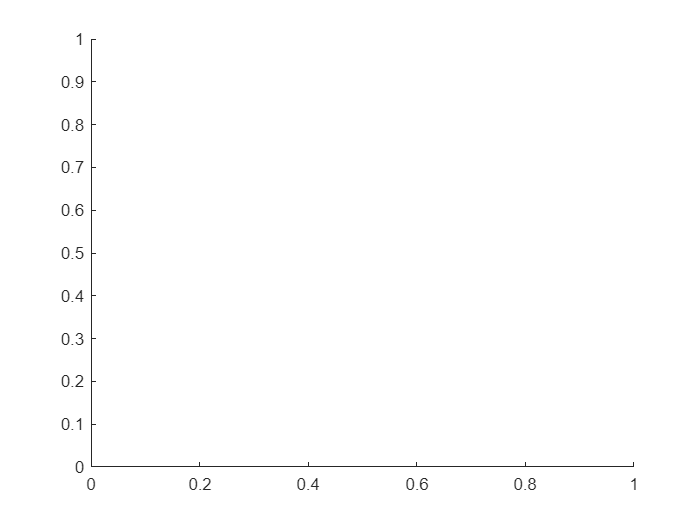

Invalid indexing operation.

% Create a VideoReader object
videoFile = 'input.mp4';
videoReader = VideoReader(videoFile);

% Initialize variables
isMapInitialized = false;
preFeatures = [];
prePoints = [];
currFrameIdx = 1;

% Create a figure for visualization
figure;
axis tight;
set(gca,'nextplot','replacechildren');

% Read and process frames
while hasFrame(videoReader)
    % Read the current frame
    currI = readFrame(videoReader);

    % Detect and extract ORB features
    scaleFactor = 1.2;
    numLevels = 8;
    numPoints = 1000;
    [currFeatures, currPoints] = helperDetectAndExtractFeatures(currI, scaleFactor, numLevels, numPoints);

    if ~isMapInitialized
        preFeatures = currFeatures;
        prePoints = currPoints;
        isMapInitialized = true;
        continue;
    end

    % Find putative feature matches
    indexPairs = matchFeatures(preFeatures, currFeatures, 'Unique', true, ...
        'MaxRatio', 0.9, 'MatchThreshold', 40);

    % If not enough matches are found, skip to the next frame
    minMatches = 100;
    if size(indexPairs, 1) < minMatches
        preFeatures = currFeatures;
        prePoints = currPoints;
        continue;
    end

    % Triangulate two views to obtain 3-D map points
    % Assume you have a function helperTriangulateTwoFrames for this purpose
    % Replace rigidtform3d with the appropriate transformation
    minParallax = 1; % In degrees
    [isValid, xyzWorldPoints, inlierTriangulationIdx] = helperTriangulateTwoFrames(...
        rigidtform3d, relPose, prePoints(indexPairs(:,1),:), currPoints(indexPairs(:,2),:), intrinsics, minParallax);

    if ~isValid
        preFeatures = currFeatures;
        prePoints = currPoints;
        continue;
    end

    % Visualize depth information
    depthValues = xyzWorldPoints(:, 3);
    colormap('jet');

    
    scatter(currPoints(:, 1), currPoints(:, 2), 10, depthValues, 'filled');
    colorbar;
    title(['Frame: ', num2str(currFrameIdx)]);

    % Update variables for the next iteration
    preFeatures = currFeatures;
    prePoints = currPoints;
    currFrameIdx = currFrameIdx + 1;

    % Pause to display the frame
    pause(0.1);
end